# **LEDS Exam: July 25, 2023 **

# **Gabriele Ruscelli**

# Exercise 1: Estimation 

In this exercise you are asked to estimate an unknown linear model and display it.

**Understand the model structure**: The provided signals refer to either a ARX or a FIR model. It is not as easy as finding out the difference from an AR and ARX model. This means you have to try the identification and validation procedure **twice**, one assuming you have a FIR and one assuming you have an ARX model.

**Define the required estimation algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. In this particular case you are asked to implement the least squares functions to estimate both ARX and FIR models.

**Estimate the model order: **describe the criteria you plan to use and add brief description of the matlab function you implemented to do that. In this particular case you are asked to implement the functions to estimate the order for both ARX and FIR models.

**Validate the model: **describe the criteria with hypothesis testing you plan to use to get model validation and add a description of the matlab functions you implemented to do that. At this point you should already have found out the structure of the model, comment on it.

clear 
close all
addpath ./Functions;

## General considerations

First of all it is necessary to collect data from the model.

**TRAINING SET**

N=10000; 
Student = 'Gabriele Ruscelli';
Matriculation = '0001103802';
[Measurements] = IdentifyThis(N, Student, Matriculation);
u=Measurements.u;
y=Measurements.y;

**VALIDATION SET**

N_validation=30000; 
[Measurements] = IdentifyThis(N_validation, Student, Matriculation);
u_validation=Measurements.u;
y_validation=Measurements.y;

Let's plot a slice of the two data set.

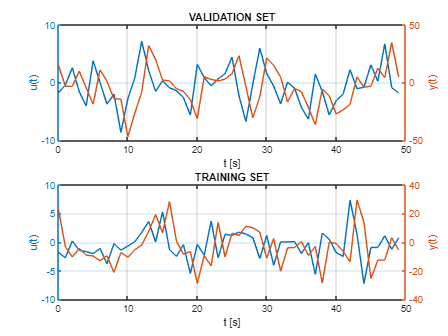

time=[0:1:N-1]';
figure();
subplot(2,1,1)
ax=plotyy(time(1:50),u(1:50),time(1:50),y(1:50));
grid on;
ylabel(ax(1), 'u(t)');
ylabel(ax(2), 'y(t)');
xlabel('t [s]');
title('VALIDATION SET');
subplot(2,1,2)
ax=plotyy(time(1:50),u_validation(1:50),time(1:50),y_validation(1:50));
grid on;
ylabel(ax(1), 'u(t)');
ylabel(ax(2), 'y(t)');
xlabel('t [s]');
title('TRAINING SET');

First of all let's analyze the differences between ARX and FIR models.

FIR models are static models, the output at time t do not depend on present or past output samples. The complexity order of the model is p=n.

ARX models are dynamic models, the output at time t do depend on past output samples. ARX models are more general than FIR models, in fact FIR models are a particular case of ARX models in which all the dynamic coefficients are set to 0. The complexity of an ARX model is p=2*n. 

Let's analyze the quality of the input using the autocorrelation function.

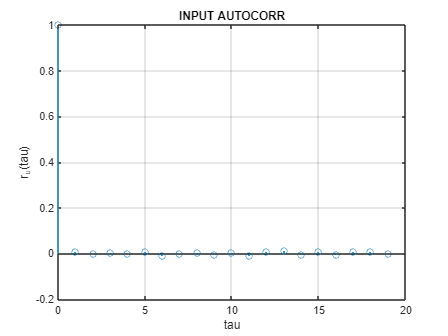

r_u=autocorr(u);
figure();
stem(time(1:20),r_u(1:20));
grid on;
ylabel( 'r_u(tau)');
xlabel('tau');
title('INPUT AUTOCORR');

The autocorrelation function of the input is similar to the autoccorrelation function of a white noise, that is good since a white process is persistently exciting of any order, therfore the input is good for estimation purposes. It is possible to test the whiteness of the input, for this purpose we can use the chi square whiteness test. Setting the power of the test to 0.01 we get... (should be white)

chi2_whitness_test(r_u,0.01,length(r_u),length(u));

chi square whitness test: the sequence is white


## Model complexity selection

For the purpose of model complexity analysis we will use MDL criterion. The MDL function returns in logartithmic scale the cost funtion plus a penality term for high complexity orders.

L=50;
J=zeros(L,1);
Theta=zeros(L,1);

**FIR**

for n=1:L
    Theta=LS(y,u,n,0);    %0 for FIR %1 for ARX
    J(n)=MDL(y,u,Theta,0);
end
[value,min_FIR]=min(J);

Let's plot the minimum value of the MDL function and the corresponding n.

disp([value,min_FIR]); 

   1.0e+05 *

   -6.3386    0.0003



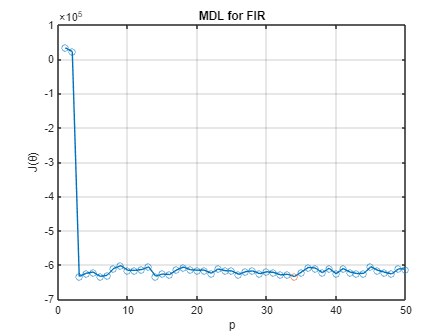

figure();
plot(J,'-o');
hold on;
grid on;
plot(min_FIR,J(min_FIR),'o');
ylabel('J(\theta)');
xlabel('p');
title('MDL for FIR');
hold off;

The MDL do not concludes a clear result, in fact if we increase the size of the data set, the corresponding p to the minimum of the MDL function may vary considerably, but what does not change is that from complexity 2 to 3 there is a brutal change of the MDL function and from that point on increasing the order of the model do not seem to improve the system identification. For these reasons we will choose the FIR model complexity as p=3.

**ARX**

for n=1:L
    Theta=LS(y,u,n,1);
    J(n)=MDL(y,u,Theta,1);
end

[value,min_ARX]=min(J);

Let's plot the minimum value of the MDL function and the corresponding n.

disp([value, min_ARX]);

   1.0e+05 *

   -6.3286    0.0001



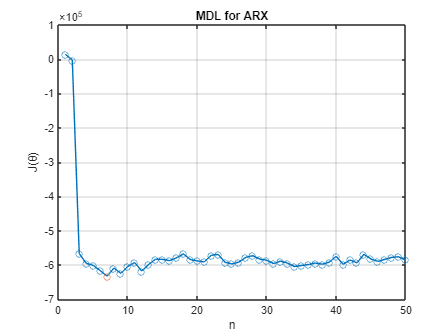

figure();
plot(J,'-o');
grid on;
hold on;
plot(min_ARX,J(min_ARX),'o');
ylabel('J(\theta)');
xlabel('n');
title('MDL for ARX');
hold off;

As for FIR model the MDL do not concludes a clear result, in fact increasing the number of the data collected the minimum of the MDL function may considerably, but what does not change is that from n equals to 2 to n equals to 3 there is a brutal change of the MDL function and from that point on increasing the order of the model do not seem to improve the system identification. For these reasons we will choose the ARX model complexity as p=2*n=6.

**WARNING**: A very important aspect is that the minimum of the MDL function reaches very small values and since we are in logaritmic scale we can approximately evaluate the const function applying these formula J(theta) = exp(-6000)->0 ...

This means that we are dealing with very small residuals, in fact later on we will see that they tends to 0, probably this may also cause some computational problem with matlab and it also may get difficult to analyze the whiteness of the resiuals.

## Model estimation

**FIR** estimation with complexity p=3.

n_FIR=3; %hint for correction: try to set n=2 
Theta_FIR=LS(y,u,n_FIR,0);

Let's desplay the estimated FIR coefficents 

fprintf('b1Hat = %.4f, b2Hat = %.4f,b3Hat = %.4f\n',Theta_FIR(1),Theta_FIR(2),Theta_FIR(3));%comment this to see what happens if n=2

b1Hat = 4.7109, b2Hat = 1.3102,b3Hat = 0.9540


We can compute the cost function using the validation set, we will use this result later for validation purposes. (F test, see "conclutions")

J_FIR=Cost_function(y_validation,u_validation,Theta_FIR,0);

**ARX** estimation with complexity p=3.

n_ARX=3;
Theta_ARX=LS(y,u,n_ARX,1);

Let's desplay the estimated ARX coefficents.

fprintf('a1Hat = %.4f, a2Hat = %.4f, a3Hat = %.4f\n',Theta_ARX(1),Theta_ARX(2),Theta_ARX(3));

a1Hat = -0.0000, a2Hat = 0.0000, a3Hat = -0.0000


fprintf('b1Hat = %.4f, b2Hat = %.4f, b3Hat = %.4f\n',Theta_ARX(4),Theta_ARX(5),Theta_ARX(6));

b1Hat = 4.7109, b2Hat = 1.3102, b3Hat = 0.9540


Note that the cofficients proportional to the output are very little, **the ARX model tends to behave like a FIR model**! 

We can compute the cost function using the validation set, we will use this result later for validation purposes

J_ARX=Cost_function(y_validation,u_validation,Theta_ARX,1);

## Model validation

**FIR validations tests**

Let's compute the sequence of residuals, and its autocovariance using the validation set (**WARNING**: as previously said the residuals are very small, that is generally a good sign since it means that the estimated model predicts well the real model,but even if we round the vector to the power of -5 we would get an array of zeros, this may cause some problem in the analysis)

In order to evaluate the autocorrelation I used the crosscorr function, in this way one can choose the size of the test m as prefered.

n=n_FIR;
m=100;
H=myHank(u_validation,n);
epsilon=y_validation(n+1:N_validation)-H*Theta_FIR

epsilon = 	1.0e+-13 *

    0.0089
   -0.0888
   -0.0888
   -0.1066
   -0.0533
   -0.2487
         0
   -0.1066
   -0.0355
   -0.0044


eps=round(epsilon,5)%the order of the residuals is very small

eps =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r_e=xcorr(epsilon,epsilon,m);
m=(length(r_e)-1)/2;
r_e=r_e/r_e((m+1)); %normalized autocorrelation
r_e=r_e(m+1:end);

Let's plot its autocorrelation keeping in mind that it should be similar to the autocorrelation of a zero mean white noise.

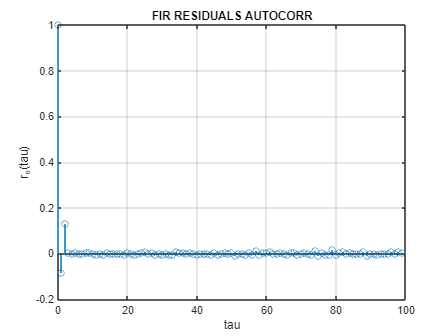

figure();
stem(time(1:m),r_e(1:m));
grid on;
ylabel( 'r_e(tau)');
xlabel('tau');
title('FIR RESIDUALS AUTOCORR');

**FIR WHITENESS TESTS**

Testing the whiteness may result very difficult since the array that we are analysing is composed by verly little values, running many time this code it would be possible to see that many times the test fails many time and even if we increase the size of the validation set  (N_validation)  the results continuosly change and they don't appear to be fixed. I think this problem is caused by the uncertaintes due to matlab.

alpha_whitness=0.3;
m=length(r_e);

**Anderson whiteness test** this test checks if the residual sequence is a zero mean white process

number_of_fails=Anderson_test(r_e,alpha_whitness,m,N_validation)

number_of_fails = 19

if(Anderson_test(r_e,alpha_whitness,m,N_validation)/m<=alpha_whitness)
    disp('Anderson whitness test: the sequence is white');
else
    disp('Anderson whitness test: the sequence is not white');
end

Anderson whitness test: the sequence is white


**FIR CROSS-CORRELATION TEST**

cross-correlation test checks if the input and the residuals are correlated

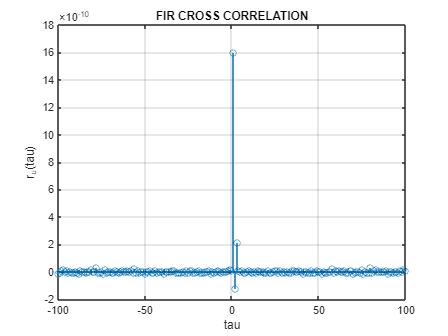

m_cross=100;
alpha_cross=0.05;
r_eu=xcorr(epsilon(1:end),u_validation(n+1:end),m_cross);
tau=[-m_cross:1:m_cross]';
figure();
stem(tau,r_eu)
grid on;
ylabel( 'r_e_u(tau)');
xlabel('tau');
title('FIR CROSS CORRELATION');

chi2_cross_test(r_eu,u_validation,alpha_cross,m_cross,N_validation);

u and epsilon are uncorrelated


**FIR CROSS-VALIDATION**

using plots we can check the capability to predict the the output using a validation set.

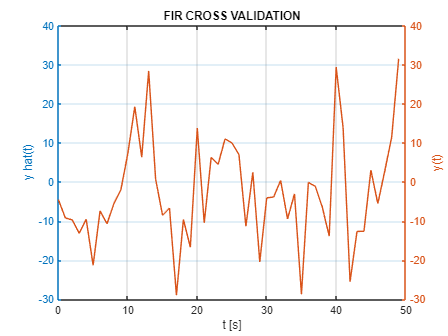

y_hat_FIR=myHank(u_validation,n)*Theta_FIR;

figure();
ax=plotyy(time(1:50),y_hat_FIR(1:50),time(1:50),y_validation(n+1:n+50));
grid on;
ylabel(ax(1), 'y hat(t)');
ylabel(ax(2), 'y(t)');
xlabel('t [s]');
title('FIR CROSS VALIDATION');

It looks like that this model well predict the real model behaviour ((maybe a little too much).

**ARX validations test**

**NOTE: the same analysis is done for ARX model but bear in mind that the estimated ARX model is practically a FIR model since the dynamic coefficents are around 0. The main differences between the two models are that the ARX whiteness test fails more times than the one for FIR models even if the two of them are close to be the same model. You should see the fail number of the Anderson test desplyaed by the code, you can run the code and notice it by yourself.**

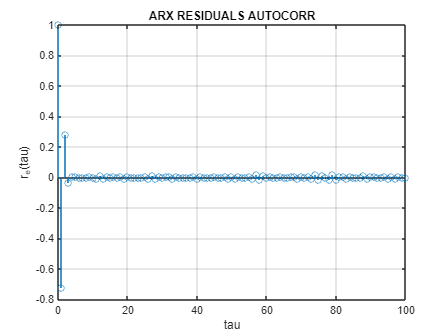

n=n_ARX;
H=[-myHank(y_validation,n) myHank(u_validation,n)];
epsilon=y_validation(n+1:N_validation)-H*Theta_ARX;
r_e=xcorr(epsilon,epsilon,m);
m=(length(r_e)-1)/2;
r_e=r_e/r_e((m+1)); %normalized autocorrelation
r_e=r_e(m+1:end);
figure();
stem(time(1:m),r_e(1:m));
grid on;
ylabel( 'r_e(tau)');
xlabel('tau');
title('ARX RESIDUALS AUTOCORR');

**ARX WHITNESS TESTS**

m=length(r_e);

Anderson whiteness test this test checks if the residual sequence is a zero mean white process

failed_count=Anderson_test(r_e,alpha_whitness,m,N_validation)

failed_count = 39

if(Anderson_test(r_e,alpha_whitness,m,N_validation)/m<=alpha_whitness)
    disp('Anderson whitness test: the sequence is white');
else
    disp('Anderson whitness test: the sequence is not white');
end

Anderson whitness test: the sequence is not white


**ARX CROSS-CORRELATION TEST**

cross-correlation test checks if the input and the residuals are correlated

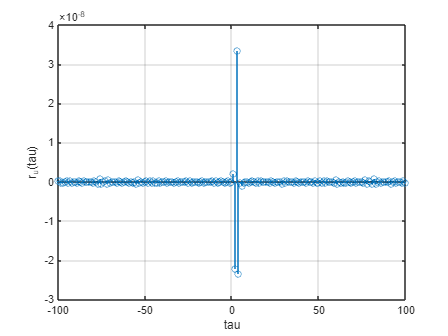

r_eu=xcorr(epsilon(1:end),u_validation(n+1:end),m_cross);
tau=[-m_cross:1:m_cross]';
figure();
stem(tau,r_eu)
grid on;
ylabel( 'r_e_u(tau)');
xlabel('tau');

chi2_cross_test(r_eu,u_validation,alpha_cross,m_cross,N_validation);

u and epsilon are uncorrelated


**FIR CROSS-VALIDATION**

using plots we can check the capability to predict the the output using a validation set.

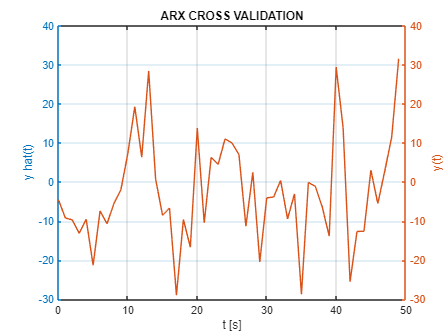

H=[-myHank(y_validation,n) myHank(u_validation,n)];
y_hat_ARX=H*Theta_ARX;

figure();
ax=plotyy(time(1:50),y_hat_ARX(1:50),time(1:50),y_validation(n+1:n+50));
grid on;
ylabel(ax(1), 'y hat(t)');
ylabel(ax(2), 'y(t)');
xlabel('t [s]');
title('ARX CROSS VALIDATION');

## Conclusions F_test

From the consideration we have done so far we can already assume that the model we are trying to estimate is a FIR model, to prove this I used the F test.

 Let's applay the F-test, note that for FIR models p=n and for ARX p=2*n, so, since n is the same for the two of them, the complexity class of ARX is greater than the FIR model.

alpha=0.01;
P_ARX=length(Theta_ARX);
P_FIR=length(Theta_FIR);
x=N*(J_FIR-J_ARX)/J_ARX;
if x<=chi2inv(1-alpha,P_ARX-P_FIR)
    disp('FIR MODEL IS BETTER THAN ARX');
else
    disp('FIR MODEL IS NOT SUITABLE TO DESCRIBE THE SYSTEM');
end

FIR MODEL IS BETTER THAN ARX


#### ***The estimated model is a FIR model of oreder 3 shown by the code***

fprintf('b1Hat = %.4f, b2Hat = %.4f,b3Hat = %.4f\n',Theta_FIR(1),Theta_FIR(2),Theta_FIR(3));%comment this to see what happens if n=2

b1Hat = 4.7109, b2Hat = 1.3102,b3Hat = 0.9540


clear 
close all
addpath ./Functions;

# Exercise 2: Classification 

In this exercise you are asked to create a classificator from a training set and test it on a new test set..

N=4000; 
Student = 'Gabriele Ruscelli';
Matriculation = '0001103802';
[FeatureSet] = ClassifyThose(N,Student,Matriculation);

To collect the set it is advised to use this piece of code

Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;

Then, the classification problem should be solved following the steps below:

- **Understand the feature set in space**: The provided training features are scattered in space in a particular (geometrical) way. Understand it and use it to define a "refined" feature set if needed. (Plotting them may result useful). Notice that the training set distribution in space changes at every run of the function, however the boundary shape is always the same. This can be handled easily in a well thought program.

- **Define the required classification algorithm: **describe the algorithm you plan to use and why and add brief description of the matlab function you implemented accordingly. 

- **Verify and test your classificator: **verify the obtained classificator on the provided training set and compute the related classification error. Then, try your classificator on the test set and plot your results together with the classification error on the test set.

Remember to add a brief description of the matlab function you implemented accordingly.

**P.S.: **Remember that $\varphi(t)=\left[\begin{array}{l}
1 & \bar u(t)
\end{array}\right]^{T}$ in the case of complex curves.

**P.S.: **Remember that in the case of features representing **more than two classes** you can train a classifier that divides one class with respect to all the others and you can compute one per each class against all the others. In this context, the final prediction is the maxumum value obtianed by applying each of the one-vs-the-rest classifiers to a new set of features. **If this is the case, do not plot every single 1vs1 boundary and prediction, just create the final plot with all the boundaries and the relative classes.**

Write an organic **Surname_Name.mlx **file contaning both the explanation and coding that follows the above steps of **BOTH** exercises. This will also be your final project report. Remeber to read carefully the exam description with the submission rules.

## General considerations

THS CODE HA BEEN THOUGHT TO BE VIZUALIZED SHOWING THE OUTPUT ON THE RIGHT. "VIEW"->"OUTPUT ON THE RIGHT"

The goal this peace of code is to divide the inputs of the training set on the basis of their classes.

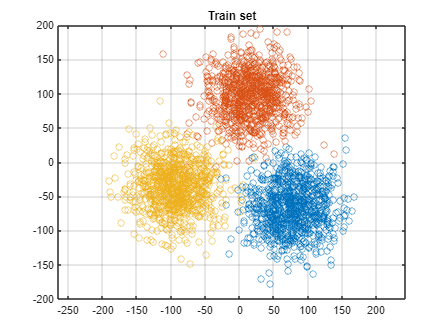

c1_count=0;
c2_count=0;
c3_count=0;
%count the number of inputs for each class
for i=1:length(Ytrain)
    if Ytrain(i)==1
        c1_count=c1_count+1;
    end
    if Ytrain(i)==2
        c2_count=c2_count+1;
    end
    if Ytrain(i)==3
        c3_count=c3_count+1;
    end
end
%initialize the vector of inputs
U1=zeros(c1_count,2);
U2=zeros(c2_count,2);
U3=zeros(c3_count,2);

c1_count=1;
c2_count=1;
c3_count=1;
%assign the inputs to the class
for i=1:length(Ytrain)
    if Ytrain(i)==1
        U1(c1_count,:)=Utrain(i,:);
        c1_count=c1_count+1;
    end
    if Ytrain(i)==2
        U2(c2_count,:)=Utrain(i,:);
        c2_count=c2_count+1;
    end
    if Ytrain(i)==3
        U3(c3_count,:)=Utrain(i,:);
        c3_count=c3_count+1;
    end
end

figure();
plot(U1(1:end,1),U1(1:end,2),'o');
hold on;
xlim([-200 200])
ylim([-200 200])
plot(U2(1:end,1),U2(1:end,2),'o');
plot(U3(1:end,1),U3(1:end,2),'o');
grid on 
axis equal;
title('Train set');
hold off;

we may assume that the 3 classes are gaussian distributed with same coviariance matrices.

## Linear discriminant analysis

Let's compute the required parameters of the linear discriminant analysis and than plot the linear discriminant boundaries.

%mean values
disp('mean values')

mean values


mu1=mean(U1)

mu1 =    78.2575  -65.4858


mu2=mean(U2)

mu2 =    16.2308   97.5498


mu3=mean(U3)

mu3 =   -93.0371  -34.6859


%covariance matrices
disp('covariance matrices')

covariance matrices


cov1=cov(U1)

cov1 = 	1.0e+03 *

    1.0584    0.0615
    0.0615    1.1505


cov2=cov(U2)

cov2 = 	1.0e+03 *

    1.0742    0.0221
    0.0221    1.1446


cov3=cov(U3)

cov3 = 	1.0e+03 *

    1.0471   -0.0250
   -0.0250    1.0953


%mean covariance matrix
disp('mean covariance matrix (sigma)')

mean covariance matrix (sigma)


sigma=(cov1+cov2+cov3)/3

sigma = 	1.0e+03 *

    1.0599    0.0195
    0.0195    1.1301


inv_sigma=inv(sigma)

inv_sigma = 	1.0e+-3 *

    0.9438   -0.0163
   -0.0163    0.8852


%class probability
disp('class probability')

class probability


P1=c1_count/length(Ytrain)

P1 = 0.3361

P2=c2_count/length(Ytrain)

P2 = 0.3257

P3=c3_count/length(Ytrain)

P3 = 0.3393

%decision boundaries parameters
disp('beta and beta zero')

beta and beta zero


beta1=mu1/sigma

beta1 =     0.0749   -0.0592


beta2=mu2/sigma

beta2 =     0.0137    0.0861


beta3=mu3/sigma

beta3 =    -0.0872   -0.0292


beta1_0=-0.5*mu1*inv_sigma*mu1'+log(P1)

beta1_0 = -5.9621

beta2_0=-0.5*mu2*inv_sigma*mu2'+log(P2)

beta2_0 = -5.4318

beta3_0=-0.5*mu3*inv_sigma*mu3'+log(P3)

beta3_0 = -5.6454

%plot of the decision boundaries on the train set
disp('plot of the decision boundaries')

plot of the decision boundaries


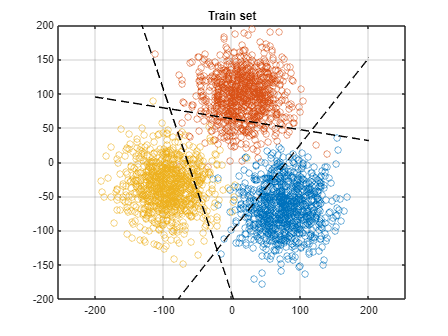

figure();
plot(U1(1:end,1),U1(1:end,2),'o');
hold on;
xlim([-200 200])
ylim([-200 200])
plot(U2(1:end,1),U2(1:end,2),'o');
plot(U3(1:end,1),U3(1:end,2),'o');
grid on 
axis equal;
title('Train set');
xspace = -200:1:200;
BoundaryLine1 = -(beta1_0 + xspace.*beta1(1))./beta1(2);
BoundaryLine2 = -(beta2_0 + xspace.*beta2(1))./beta2(2);
BoundaryLine3 = -(beta3_0 + xspace.*beta3(1))./beta3(2);
plot(xspace,BoundaryLine1,'--k');
plot(xspace,BoundaryLine2,'--k');
plot(xspace,BoundaryLine3,'--k');
hold off

%estimate of the posterior probabilities
disp('evaluate z(t) for each U using the test set')

evaluate z(t) for each class using the test set


z1=Utest*beta1'+beta1_0

z1 =     5.6169
  -12.0728
  -10.2265
  -10.7851
   11.1419
   -8.6438
  -10.2457
   -8.0156
    0.7526
  -10.9339


z2=Utest*beta2'+beta2_0

z2 =    -7.5940
    3.4874
    3.5168
    1.2796
  -17.8824
  -12.5974
  -10.8340
    5.6765
   -8.9090
  -11.6582


z3=Utest*beta3'+beta3_0

z3 =   -14.7896
   -8.6962
  -10.5331
   -7.7208
   -9.7790
    4.2359
    4.0183
  -14.8842
   -8.6967
    5.5264


f1=zeros(length(Utest),1);
f2=zeros(length(Utest),1);
f3=zeros(length(Utest),1);
Yclassification=zeros(length(Utest),1);
%assign the class
%estimate of the posterior probabilities
disp('assign each u of the test set to one of the classes using the gaussian distribution functions')

assign each u to one of the classes using the gaussian distribution functions


for i=1:length(Utest)
    f1(i)=exp(z1(i))/(exp(z1(i))+exp(z2(i))+exp(z3(i)));
    f2(i)=exp(z2(i))/(exp(z1(i))+exp(z2(i))+exp(z3(i)));
    f3(i)=exp(z3(i))/(exp(z1(i))+exp(z2(i))+exp(z3(i)));
    if(f1(i)>f2(i))
        if(f1(i)>f3(i))
            Yclassification(i)=1;
        end
    end
    if(f2(i)>f1(i))
        if(f2(i)>f3(i))
            Yclassification(i)=2;
        end
    end
    if(f3(i)>f1(i))
        if(f3(i)>f2(i))
            Yclassification(i)=3;
        end
    end
end
Yclassification

Yclassification =      1
     2
     2
     2
     1
     3
     3
     2
     1
     3



%final result: PLOT same code of the previous plot + linear decison
%boundaries
c1_count=0;
c2_count=0;
c3_count=0;

for i=1:length(Yclassification)
    if Yclassification(i)==1
        c1_count=c1_count+1;
    end
    if Yclassification(i)==2
        c2_count=c2_count+1;
    end
    if Yclassification(i)==3
        c3_count=c3_count+1;
    end
end

U1=zeros(c1_count,2);
U2=zeros(c2_count,2);
U3=zeros(c3_count,2);

c1_count=1;
c2_count=1;
c3_count=1;

miss_count=0;
disp('Plot the classified points of the test set');

Plot the classified points of the test set


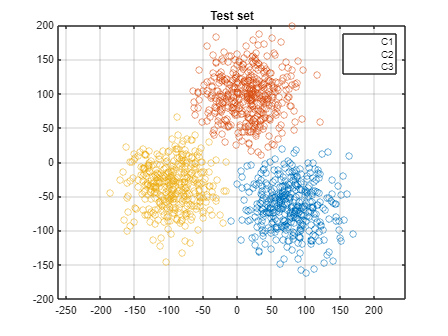

for i=1:length(Yclassification)
    %count the missiclsified outputs
    if not(Yclassification(i)==Ytest(i))
        miss_count=miss_count+1;
    end
    if Yclassification(i)==1
        U1(c1_count,:)=Utest(i,:);
        c1_count=c1_count+1;
    end
    if Yclassification(i)==2
        U2(c2_count,:)=Utest(i,:);
        c2_count=c2_count+1;
    end
    if Yclassification(i)==3
        U3(c3_count,:)=Utest(i,:);
        c3_count=c3_count+1;
    end
end

figure();
plot(U1(1:end,1),U1(1:end,2),'o');
hold on 

xlim([-200 200])
ylim([-200 200])
plot(U2(1:end,1),U2(1:end,2),'o');
plot(U3(1:end,1),U3(1:end,2),'o');

legend({'C1','C2','C3'});
grid on 

title('Test set');
axis equal

disp('evaluate the number of missclassified points and its percentual value');

evaluate the number of missclassified points and its percentual value


miss_count

miss_count = 3

miss_count_perc=100*miss_count/length(Yclassification)

miss_count_perc = 0.2500

As shown for the the missclissified points are very small with respect to the size of the test set so the model used for the classification works fine.